# Plotting Beacon Data in Global Frame

Objective: This script will get the readings from the Beacon sensor and transform the data from the sensor frame to the robot frame to the global frame using the *transform_points *function. It will then plot the sensed beacon locations in the **global frame**. 

Cheat Sheet: In this script, you will capture the data from the Beacon sensor using the function *RealSenseTag(robotObj,map)*. This function takes the image from the forward camera and checks if any AR tags are within the field of view. If the Beacon sensor identifies any tags, for each identified tag it will return an array containing information about the tag, such as its x and y positions in the sensor frame. If no tags are detected, it will return an empty array.

For more information about how the function `RealSenseTag `works and the values it return`s` for each tag, refer to the CreateRobot documentation.

help RealSenseTag %in Command Window

--- help for CreateRobot/RealSenseTag ---

  tags = RealSenseTag(obj,map) Finds AprilTags in the image from the
  camera. Returns the id of the AprilTag, position in the frame of the
  camera, and rotation about its center.
 
  Inputs:
  obj: CreateRobot object
  map: struct of map data from loadMap
 
    Camera coordinate frame is defined as:
        x - axis points out of camera (depth)
        y - axis points left
        z - axis points up
 
    Each row of the array is [dt id x y rot]
    
    dt = The delay from when the tag was requested
    id = The id number of the AprilTag
    x = The x-distance of the AprilTag in the camera coordinate frame
    y = The y-distance of the AprilTag in the camera coordinate frame
    rot = The orientation of the tag, in radians
 
    If no tags are detected, returns an empty array
  Check for valid input
  removing IF statement so this can be called on a static robot
  object outside of the simulator [AA]



Helper Functions used in this exercise:

- plot_beacon_transform*: *Plots the beacons detected in the global frame

**EXERCISE:**

After loading the map and pressing the "Read Sensors" button in the Simulator, you will have access to the CreateRobot object (*robotObj***) **that represents the current state of the robot. 

Complete the code below to:

- Obtain the beacon pose in the robot frame.

- Obtain the current pose of the Create robot in the global frame.

- Get the Beacon sensor data.

- Identify the location of every detected tag in the global frame. Just as was the case with the LIDAR sensor, you will need to transform the x,y location of each detected tag from the sensor frame to the robot frame, and from the robot frame to the global frame. 

**COMPLETE THE CODE BELOW**

%1. Obtain the beacon pose in the robot frame.

% Write code below to define the Beacon pose based on the robot's radius.
% Remember that the robot reference frame always defines the robot position
% at [0; 0; 0].
robotRadius = % YOUR CODE HERE
beacon_pose =  % YOUR CODE HERE


%2. Obtain the robot pose in the global frame.

% Write code below to obtain the current x,y, theta position of the Create
% robot in the global frame.

[x, y, th]=  % YOUR CODE HERE
robot_pose = % YOUR CODE HERE

%3. Read Beacon Data
tags = % YOUR CODE HERE


%4. Identify the location (in the global frame) of every tag that the beacon sensor
% deteted.

% The code below initializes variable dataxy_global to save the global location of tags.
% This is a 2-by-N matrix, where each column is
% the x, y location of the beacon
dataxy_global = zeros(2,size(tags,1)); 


% Write code below that loops through every tag that the beacon sensor detected, 
% and transforms the x, y position of the tag from sensor frame to robot frame, 
% and then from robot frame to global frame.
% The global x,y position of each tag should be stored in dataxy_global.

% YOUR CODE HERE

  

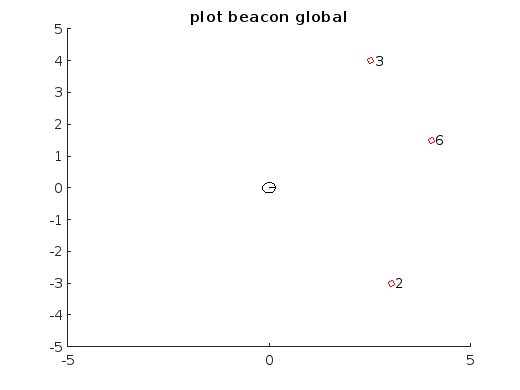

% --- Plot ----
plot_beacon_transform(tags, dataxy_global, robot_pose, robotRadius); 

Expected Results: 

Because you are plotting the beacon data in the **global frame**, you should see the beacon plotted just as you would see the beacons in the map in the simulator.

Check your Comprehension: 

Is the beacon position plotted as expected? Move the robot around the map facing different beacons and compare the plots. By moving the robot around, can you define the sensor footprint of the beacon sensor?